# **MATLAB REVISION 1**

Please complete the following problems in this Livescript unless otherwise indicated. Remember to create a folder with the name Tutorial4_username (e.g. if your username is abc, then Tutorial4_abc) to put all the files and figures related to the Tutorial (including this Livescript). When you are finished, zip the folder and upload it to the BlackBoard Assignment submission box. 

This tutorial is a revision of the concept you have learned so far, and helping you on the way to becoming an independent matlab programmer able to find the resources you need. There will be a fair amount of use of the documentation, and why not, Google. Here are some useful links to get you started, but you can find more information on your own:

- [The MATLAB Plot Gallery ](https://www.mathworks.com/products/matlab/plot-gallery.html)

- [MATLAB 2D and 3D plots](https://www.mathworks.com/help/matlab/2-and-3d-plots.html)

- [MATLAB Line properties](https://www.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.line-properties.html)

### Problem R1

In this example you are going to play around with the function **linspace** and use it to practice plotting in different styles.

Search the documentation for the function **linspace** to learn the syntax for its use. 

Consider the following function:


$$y=x^3-4x^2-x-4$$


Use linspace to split the domain $-5 \le x \le 2$ in 3, 5, 7, 10, 20 and 100 points. 

**a)** For each case, plot the value of y against x using a subplot function (in 2 rows and 3 columns). Plot all the lines in red and a solid line. Add a label to both the x and the y axes, and a title on each subplot with the words "Approximation with N points", where N is the number of points you have used to split the domain in each case. Write your code efficiently in a loop rather than repeat the code for every case.

% Generate a linear space for the domain -5>=x<=2 with N points
% (N to vary between different options) and evaluate 
% y=x^3-4x^2-x-4.

% housekeeping
clear, clc
close all

% Enter the number of points for each of the cases in an array
N=[3, 5, 7, 10, 20, 100];

figure 
% Loop to get the plot for each case of N:
for i=1:length(N)
    x=linspace(-5,2,N(i));
    for j=1:length(x)
        y(j)=x(j)^3-4*x(j)^2-x(j)-4;
    end
    % For later when we do array operators, this could also be
    % done the following line instead of the loop:
    % y=x.^3+4*x.^2-x-4;
    subplot(2,3,i)
    plot(x,y,'r-')
    xlabel('x')
    ylabel('y')
    title(['Approximation with ',num2str(N(i)),' points'])
end

**b)** Now repeat the plots, but instead of putting each in a subplot by itself, add all the plots on the same figure. Each plot should have a different line colour, alternate between solid and dotted lines, and use a different marker. Add labels on the x and y axes, and a title, and add a legend indicating which line corresponds to which value of N.  You have probably noticed that your lines are very thin, change the line thickness to 2 points. For your closed markers (i.e. a circle), add fill. Change the font in the labels and title to size 16, and the font in the axes to size 14. Change the y axes so that it shows the range $-30 \le y \le 25$. Again, try to write your code efficiently and avoid unnecessary repetition.

Optional challenge: for the 20 and 100 point cases, consider using a marker only every few points.

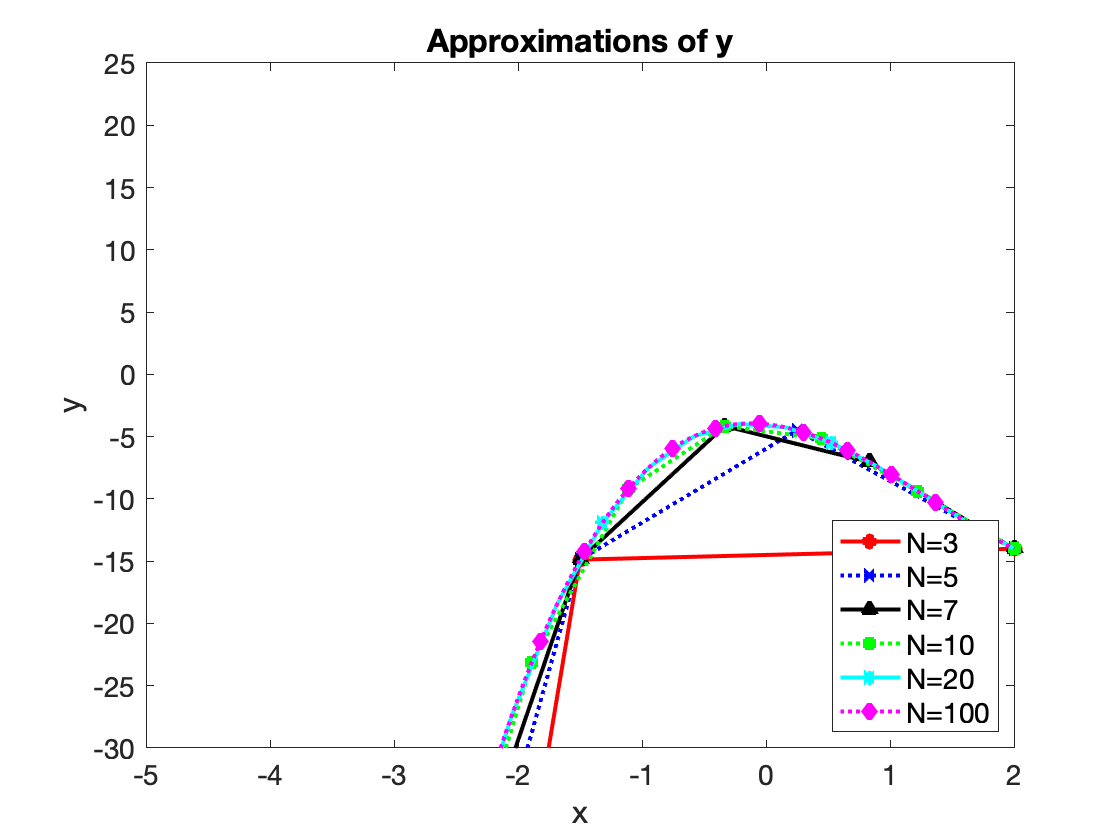

% Generate a linear space for the domain -5>=x<=2 with N points
% (N to vary between different options) and evaluate 
% y=x^3-4x^2-x-4.

% housekeeping
clear, clc
close all

% Enter the number of points for each of the cases in an array
N=[3, 5, 7, 10, 20, 100];

linecolor='rbkgcm';
linetype='-:-:-:';
marker='ox^s*d';


figure 
% Loop to get the plot for each case of N:
for i=1:length(N)
    x=linspace(-5,2,N(i));
    for j=1:length(x)
        y(j)=x(j)^3-4*x(j)^2-x(j)-4;
    end
    linestyle=[linecolor(i),linetype(i),marker(i)];
    if N(i)>10
        nm=5;
    else
        nm=1;
    end
    plot(x,y,linestyle,'LineWidth',2,'MarkerFaceColor',linecolor(i),'MarkerIndices',1:nm:length(y))
    hold on
   
end
xlabel('x','FontSize', 16)
ylabel('y','FontSize', 16)
title('Approximations of y','FontSize', 16)
legendCell = strcat('N=',string(num2cell(N)));
legend(legendCell,'Location','southeast','FontSize', 14)
ax = gca;
ax.XAxis.FontSize = 14;
ax.YAxis.FontSize = 14;
axis([-5 2 -30 25])

### Problem R2

Consider the function 		


$$z=\frac{y}{1+x^2+y^2}$$
			

For the range $-5 \le x \le 5$  and  $-5 \le y \le 5$, generate values of z using a nested loop. Then plot the function z using **contour** and **contourf **in two subplots side by side. Use 8 levels for the first plot, and 15 for the second one. Show the values of z with a colorbar.

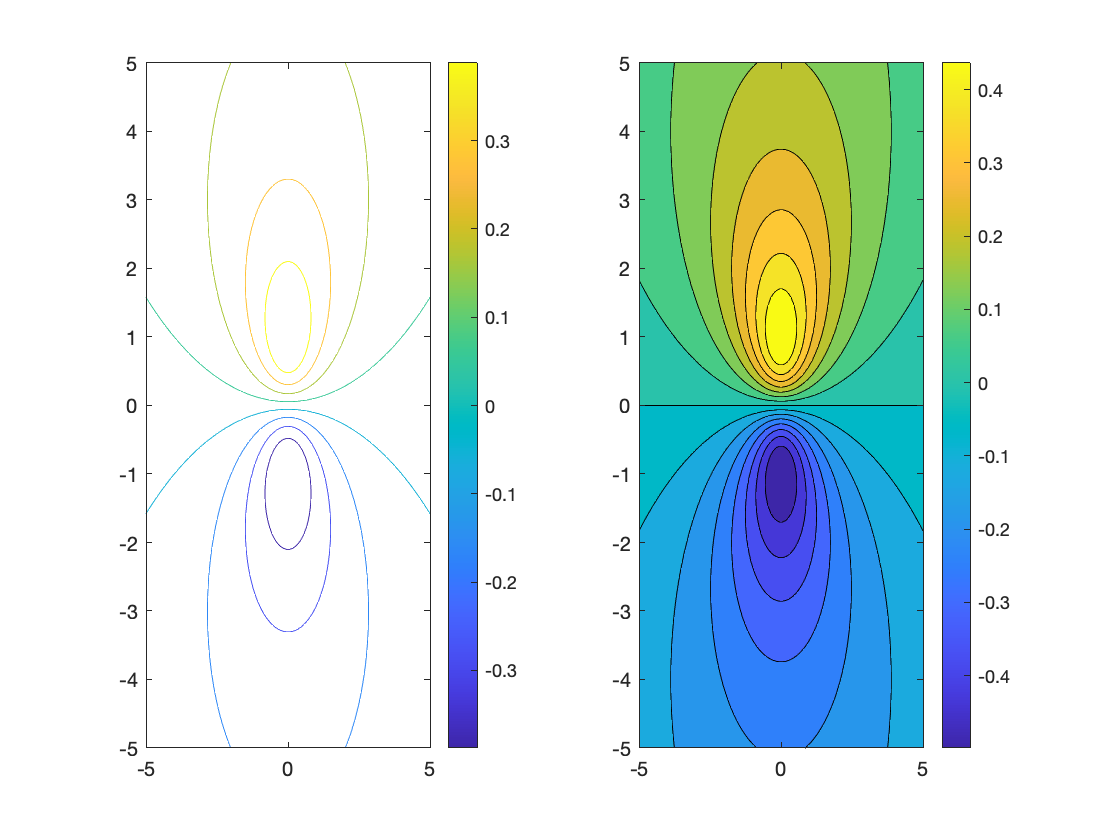

% Plot the function z with contour and contourf

%housekeeping
clear, clc
close all

% loop through all values of x and y and save x, y z into arrays
x = linspace(-5,5);
y = linspace(-5,5);

for i=1:length(x)
    for j=1:length(y)
        X(j,i)=x(i);
        Y(j,i)=y(j);
        Z(j,i)=y(j)/(1+x(i)^2+y(j)^2);
        % Note the order of the indices!!
        % According to documentation: 
        % The column and row indices of Z are the
        % x and y coordinates in the plane, respectively.
    end
end

figure
subplot(1,2,1)
contour(X,Y,Z,8)
colorbar
subplot(1,2,2)
contourf(X,Y,Z,15)
colorbar

Optional challenge: use meshgrid to generate the coordinates fo the points (we will learn this later on).				

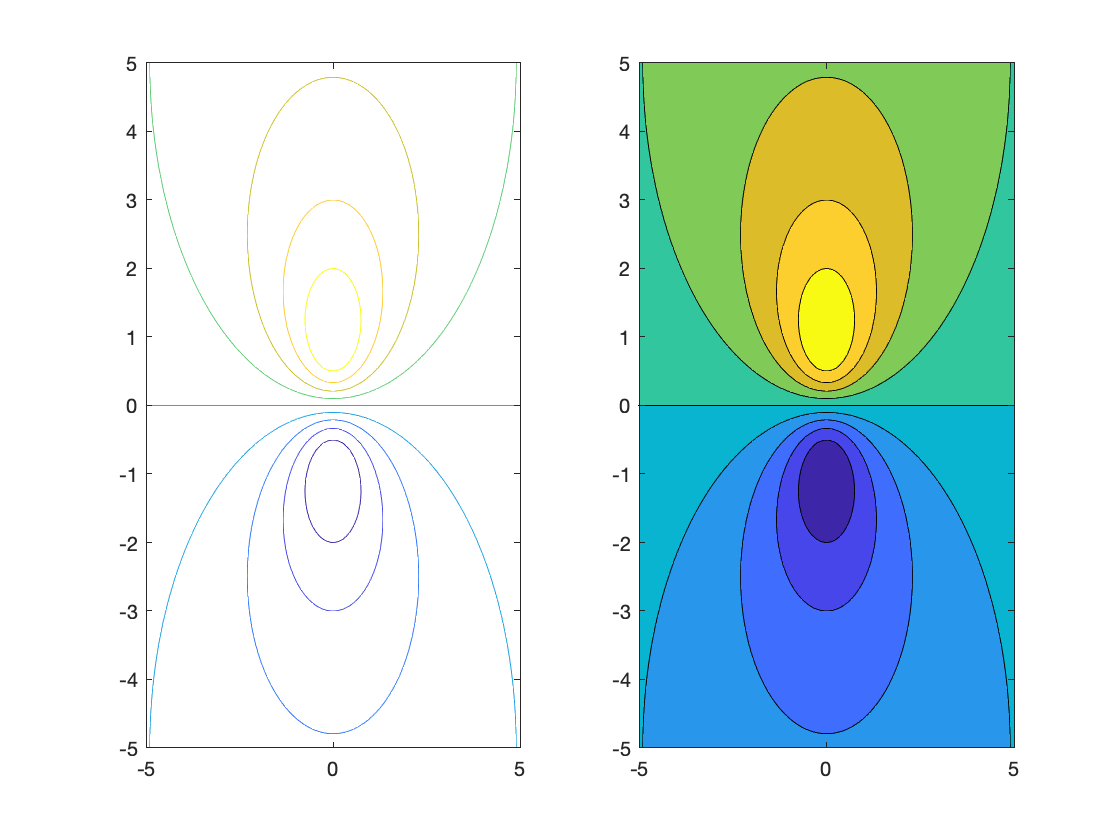

x = linspace(-5,5);
y = linspace(-5,5);
[X,Y] = meshgrid(x,y);
Z = Y./(1+X.^2+Y.^2);
figure
subplot(1,2,1)
contour(X,Y,Z)
subplot(1,2,2)
contourf(X,Y,Z)

### Problem R3

The function **sphere** can be used to generate the coordinates of a unit sphere (R=1). The input to the function N indicates the the size of the arrays used to define the sphere (the default is 20). 

a) Generate a sphere with the default number for N. Plot it in 3D using the **mesh **function. Choose a monochromatic colormap of your choice. Add a colour bar to your plot. Add a title.

% Plot a sphere using mesh

% housekeeping
clear, clc
close all

[x,y,z]=sphere;
figure
mesh(x,y,z)
title('Sphere mesh')
colormap('gray')
colorbar



b) Generate a sphere with N=100. Plot it in 3D using the **surf** function. Apply the most colourful colormap you can find. Add a colour bar to your plot and a title. Replot it next to it (using subplot) as seen from one side, by reorienting the view of the plot (programmatically, not manually). The side doesn't matter as they are all the same, your choice.

If your sphere doesn't look very round, what can you do to your axes so that it appears spherical?

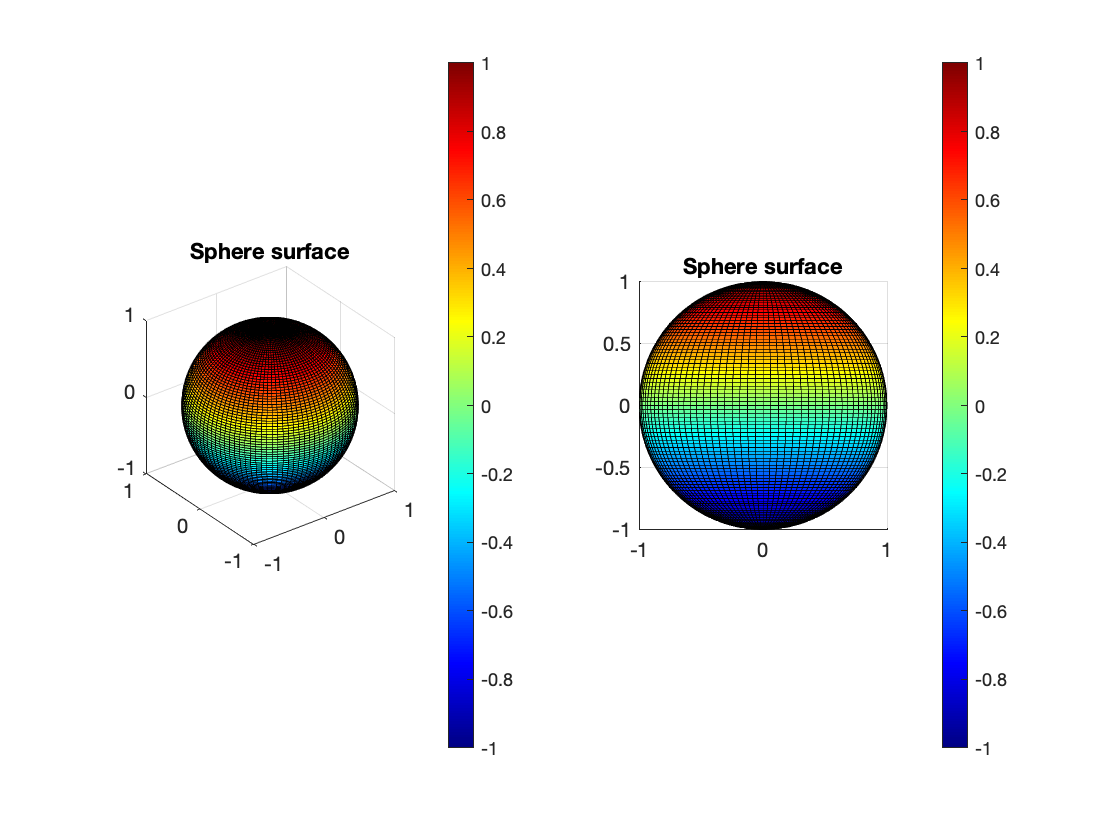

% Plot a sphere using surf

% housekeeping
clear, clc
close all

[x,y,z]=sphere(100);
figure
subplot(1,2,1)
surf(x,y,z)
title('Sphere surface')
colormap('jet')
colorbar
axis('square')
subplot(1,2,2)
surf(x,y,z)
title('Sphere surface')
colormap('jet')
colorbar
view(90,0)
axis('square')

What happens if you use **surfc **instead? 

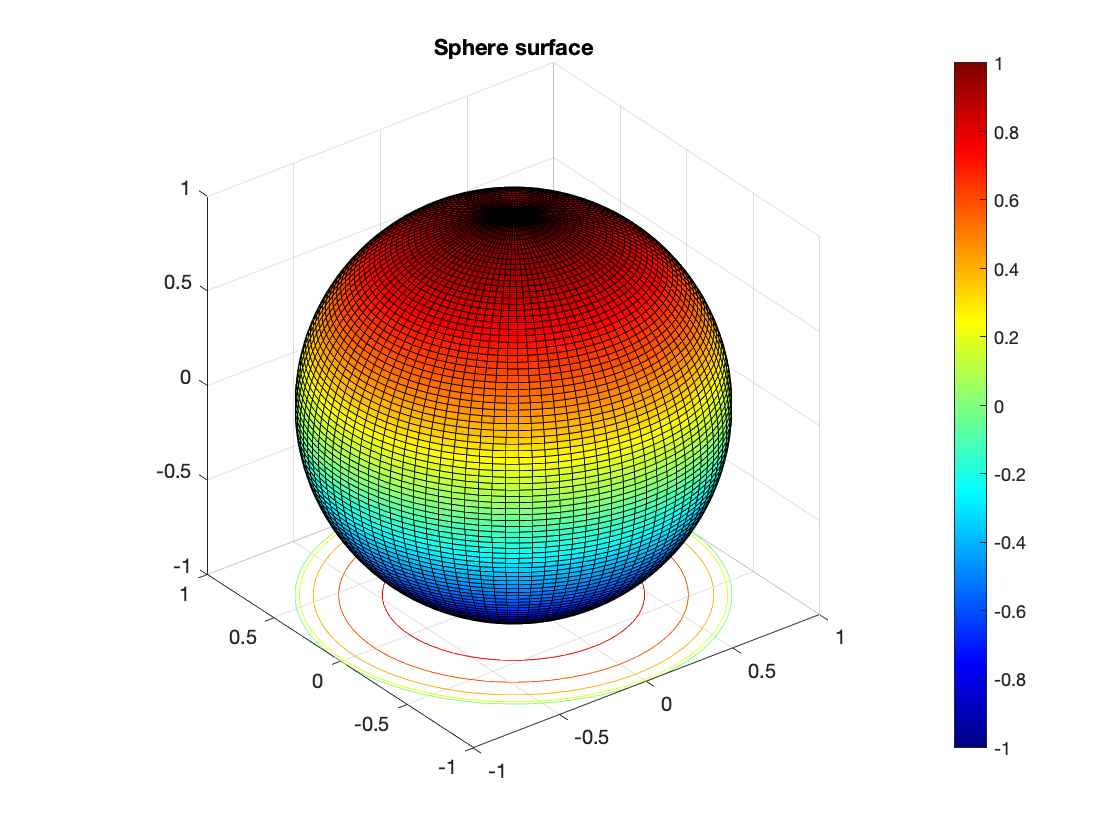

figure
surfc(x,y,z)
title('Sphere surface')
colormap('jet')
colorbar
axis('square')


% Note it shows the surf plot and the contour plot 
% projected on the axis plane below it.

### Problem R4

Bisection Method

A function is certain to have at least one root in the interval [a,b] if f(a) and f(b) have opposite signs. The bisection method is a simple algorithm to find that root. 					

The methods works by finding f(c), where c is the midpoint between a and b. The interval [a, c] or [b, c] is then chosen depending on whether f(a) and f(c) or f(c) and f(b) have opposing signs. 					

The bisection of successively smaller intervals continues until the interval is sufficiently small (x<eps) or the root (f(c) = 0) is found. 				

Implement the bisection method for a = 0 and b = 2.5 to find a root of: 

	
$$0.5x^2+0.2 \sin(10x)-1.1$$
	

Choose a reasonable tolerance.	

%Script that uses the bisection method to find a root %of 0.5*x^2+0.3*sin(10*x)-1.1 between 0 and 2.5 %Written by E. Levis, 7/1/2013

%housekeeping
clear;
clc;

%set end condition 
eps=0.0001;
%get endpoints 
a=0;
b=2.5; 
fa=0.5*a^2+0.2*sin(10.0*a)-1.1; 
fb=0.5*b^2+0.2*sin(10.0*b)-1.1;

%loop until gap sufficiently small 

while (abs(a-b)>eps)
%get midpoint
    c=(a+b)/2; 
    fc=0.5*c^2+0.2*sin(10.0*c)-1.1; %move endpoints
    if (fc==0) %check if root found
        break  %exit loop
    elseif (fa*fc<0)
        %root between a and c, replace b with c
        b=c;
        fb=fc;
    else
        %root between c and b replace a with c
        a=c;
        fa=fc;
    end 
end
disp(['The equation has a root at: ',num2str(c)])

The equation has a root at: 1.3615


%end of script

**Optional**: 							

Generalise the code for any arbitrary nth order polynomial: 

	
$$f(x)=\sum_{i=0}^{n} a_i x^i$$
				

where the constants n, $a_i$ and the search interval are user defined inputs. Display appropriate errors if $f(a)f(b) > 0$ or a predefined number of itera- tions is exceeded. 

%Script that uses the bisection method to find a root %of 0.5*x^2+0.3*sin(10*x)-1.1 between 0 and 2.5 %Written by E. Levis, 7/1/2013

%housekeeping
clear;
clc;

%set end condition 
eps=0.00001; 
Nmax=1000;

%get polynomial
npoly=input('Order of polynomial to find roots of?');

const(1)=input('Input value of the polynomial constant: ');
for i=1:npoly
    const(i+1)=input(['The coef. of the term of order '...
    ,num2str(i),' is: ']);
end
%get endpoints
a=input('Lower bound: ');
b=input('Upper bound: ');
%calculate f(a) and f(b)
fa=const(1);
fb=const(1);
for i=1:npoly
    fa=fa+const(i+1)*a^i; 
    fb=fb+const(i+1)*b^i;
end
%check if f(a) and f(b) have opposing signs
if (fa*fb>=0)
    %check if a or b are the roots
    if (fa==0)
        disp(['The function is 0 at x = ',num2str(a)]);
    elseif (fb==0)
        disp(['The function is 0 at x = ',num2str(b)]);
    else
    %display error
    disp(['The bisection method cannot be used',... 
    ' for the bounds provided']);
    end 
else
count=0;
while ((abs(a-b)>eps) & (count<Nmax))
        %get midpoint
        c=(a+b)/2;
        fc=const(1);
        for i=1:npoly
            fc=fc+const(i+1)*c^i; 
        end
        %move endpoints
        if (fc==0) %check if root found
            break  %exit loop
        elseif (fa*fc<0)
            %root between a and c, replace b with c
            b=c;
            fb=fc;
        else
            %root between c and b replace a with c
            a=c;
            fa=fc;
        end
        %increases loop counter value
        count=count+1;
end
    %output result
    disp(['The equation has a root at: ',num2str(c)])
end
%end of script

### Problem R5  (Optional)

You do not need to complete this problem in time to submit it, it is only optional if you want further practice or finish the rest very quickly. Otherwise it will be useful to practice before the exam.

Sorting Algorithm			

Sorting a set of available data is often necessary in computing. There are numerous algorithms available to sort data and MATLAB has the sortrows() function which can be readily used. 				

The selection sort algorithm is a simple yet not very efficient way of sorting datasets. The script starts by selecting the first element in the list to be sorted. It then finds the element containing the smallest value among all the cells after it. 					

If the smallest element among the remaining values is smaller than the chosen element, the contents of the two cells are switched. Otherwise the array remains as is. The algorithm then proceeds to choose the second cell in the list and finds the smallest value form the remaining unsorted cells. 				

The procedure is repeated until all values have been sorted. 		

If the array is [5, 7, 3, 1, 3, 8, 10, 6], after the first iteration the array will become: 			

        [**1**,7,3,**5**,3,8,10,6] 

Write the array after the 2nd and 3rd iterations. 

*Answer: *			

[1,**3**,3,5,**7**,8,10,6]

[1,3,**3**,**5**,7,8,10,6] 

Write a script to sort a random 1D array of user defined length, containing values between 0 and 20. Use nested for loops to write the script. Think of what you had to do manually and try replicating and automating it using the script. 

%Script to sort a random array of length n into ascending order

%housekeeping
clear
clc

%request user input
n=input('Input number of elements in random array to sort: ');
%create array
A=20*rand(n,1);
A1=A;
%start outside loop for selected cell
%no need to go to n as the last swap will happen automatically 

for i=1:n-1
    %initialize min and min location
    minval=A(i);
    minj=0;
    %find minimum of remaining array
    for j=i+1:n
        if (A(j)<minval)
            minval=A(j);
            minj=j; 
        end
    end
    %smaller value found only if minj>0
    if (minj>0)
        %swap values
        temp=A(i);
        A(i)=A(minj);
        A(minj)=temp;
    end 
end
%display the sorted matrix
disp('The original and sorted arrays are:');
disp([A1,A])
%end of script



Modify your script such that for a random 2D array, with dimensions 100 × 5, the user can choose which column to sort the entire array based on. 

%Script to sort a random array of dimensions 100x5
%the array is sorted in ascending order based on the
%contents of a column chosen by the user

%housekeeping
clear
clc
%request user input
n=0;
while ((n<1) | (n>5))
    %use while loop to trap errors
    n=input('Which column should is sort based on? ');
end
%create array
A=rand(100,5);
%start outside loop for selected cell
%no need to go to 100 as the last swap will happen automatically
for i=1:99
    %initialize min and min location
    minval=A(i,n);
    minj=0;
    %find minimum of remaining array
    for j=i+1:100
        if (A(j,n)<minval)
            minval=A(j,n);
            minj=j; 
        end
    end
    %smaller value found only if minj>0
    if (minj>0)
        %swap values for all columns
        for k=1:5
            temp=A(i,k);
            A(i,k)=A(minj,k);
            A(minj,k)=temp;
        end 
    end
end
%display the sorted matrix
disp('The sorted array is:');
disp(A)
%end of script
